# **Praktikum 5 - Shift 2**

`24 Oktober 2023`

`Nama : Tesalonika Permatasari Hutapea`

`NIM  : 10121052`

## Tips :

Anda dapat membuat *piecewise function *dengan mudah menggunakan anonymous function. Misalkan


$$f\left(x\right)=\left\lbrace \begin{array}{cc}
x^2 +1 & x<0\\
x+1 & x\ge 0
\end{array}\right.$$


Maka fungsinya adalah

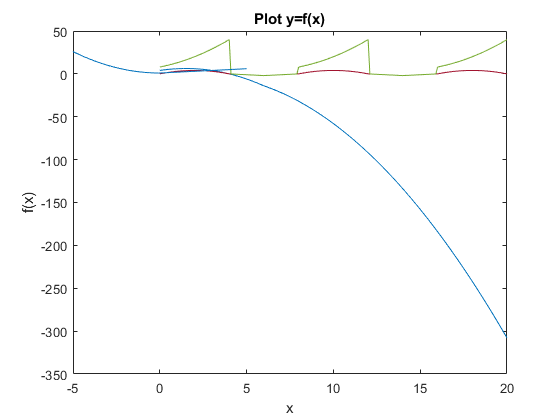

% Run program di bawah ini
% ========================
clear all;
hold off;

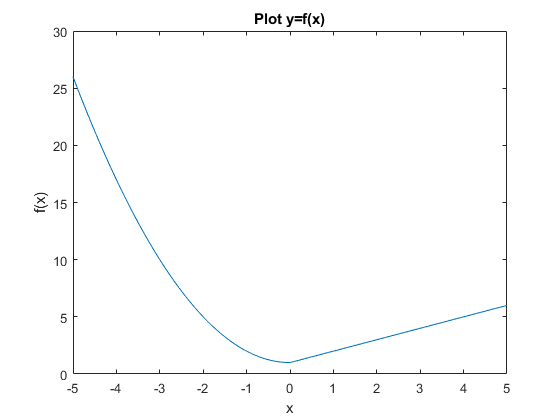

f = @(x) (x.^2 + 1).*(x<0) + (x+1).*(x>=0) ;
x = -5:0.01:5 ;
figure(1)
plot(x,f(x))
xlabel('x')
ylabel('f(x)')
title('Plot y=f(x)')

## Nomor 1

Misalkan diketahui fungsi

## 
$$f\left(x\right)=\left\lbrace \begin{array}{ll}
-{\left(x-2\right)}^2 +4 & 0\le x\le 4\\
|x-6|-2 & 4\le x\le 8
\end{array}\right.$$


adalah suatu fungsi periodik dengan periode $8$.

## Nomor 1A

Plot $f\left(x\right)$ pada interval $0\le x\le 20$!

% Ketik jawaban Anda di bawah garis
% ==================================
x = 0:0.1:20 ;
f = @(x) ((-(mod(x,8)-2).^2+4).*(0<=(mod(x,8))).*(mod(x,8)<=4) + (abs(mod(x,8)-6)-2).*((4<=mod(x,8)).*(mod(x,8)<=8)))

f = function_handle with value:
    @(x)((-(mod(x,8)-2).^2+4).*(0<=(mod(x,8))).*(mod(x,8)<=4)+(abs(mod(x,8)-6)-2).*((4<=mod(x,8)).*(mod(x,8)<=8)))


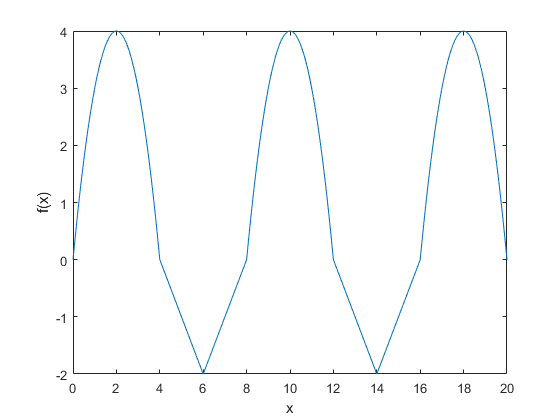

figure(2)
plot(x,f(x))
xlabel('x')
ylabel('f(x)')

## Nomor 1B

Gunakan Metode Simpson $\frac{3}{8}$ komposit untuk menghitung $\int_0^8 f\left(x\right)\;\textrm{dx}$ dengan $n=300$.

% Ketik jawaban Anda di bawah garis
% =================================
a = 0;
b = 8;
n = 300;
h= (b-a)/n;
k= 1:1:n-1;
S= f(a+k.*h);
I= 3:3:n-1;
S3= sum(S(I));
S(I)= [];
So= sum(S);

out = (3*h/8).*(f(a)+f(b)+3.*So+2.*S3);
out

out = 6.6667

## Nomor 2

Diketahui barisan titik ${\left\lbrace \left(x_n ,y_n \right)\right\rbrace }_{n=1}^N$ sebanyak $N$ suku dengan $x_n =\delta n+1$ dan $y_n =n\;\sin \;n$ yang berasal dari suatu fungsi$y=f\left(x\right)$. 

## Nomor 2A

Menggunakan titik-titik pada barisan yang diketahui, bangun fungsi `seq_trap.m `yang menerima input $N,\delta$ dan mengeluarkan aproksimasi

## 
$$\int_{x_1 }^{x_N } f\left(x\right)\;\textrm{dx}$$


dengan metode Trapesium Komposit! 

**Catatan : *****Step size *****untuk metode trapesium dibuat sama dengan nilai **$\delta$.

% Run program ini untuk cek jawaban Anda
% ======================================
N = 10 ;
delta = 0.01 ;
approx = seq_trap(N,delta) % Seharusnya didapat 0.0667

approx = 0.0667

## Nomor 2B

Tentukan fungsi $f\left(x\right)$!

Jawab :

#Maaf kak ga sempet nulis step per step


$$f\left(x\right)=\;\frac{x-1}{\delta }\ldotp \mathrm{sin}\left(\frac{x-1}{\delta }\right)$$


## Nomor 2C

Misalkan $e_N \left(\delta \right)$ adalah galat perhitungan

## 
$$\int_{x_1 }^{x_N } f\left(x\right)\;\textrm{dx}$$


secara analitik dan numerik **(menggunakan metode trapesium komposit)** . Plot $e_N \left(\delta \right)$ terhadap $\delta$ pada interval $\left\lbrack 0,5\right\rbrack$! dan tampilkan animasi plot untuk perubahan nilai $N$ (bilangan bulat) dari 2 sampai 30!

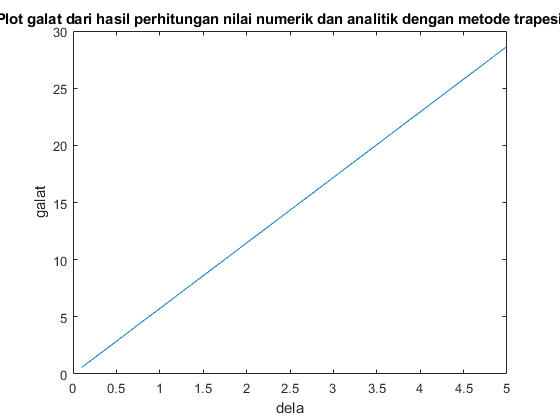

% Ketik jawaban Anda di bawah garis
% =================================
delta = 0:0.1:5;
N = 2:1:30;
f_analitik = @(N,delta) -((N-1)./delta).*cos((N-1)./delta) + sin((N-1)./delta);

for n = 1: length(N)
    for i = 1: length(delta)
        x1 = delta(i) +1;
        xn = delta(i)*N(n) + 1;
        
        f_numerik = seq_trap(N(n),delta(i));
        
        f_analitik_b = f_analitik(xn,delta(i)); % integral atas
        
        f_analitik_a = f_analitik(x1,delta(i)); % integral bawah
        
        epsilon(n,i) = abs(f_numerik - (f_analitik_b - f_analitik_b));
    end
end

for k = 1 : length(N)
    plot(delta,epsilon(k,:));
    drawnow
end
title("Plot galat dari hasil perhitungan nilai numerik dan analitik dengan metode trapesium")
xlabel("dela")
ylabel("galat")

## Nomor 2D - Bagian 1

Perhatikan bahwa ketika $\delta =0$, $e_N \left(\delta \right)$ selalu bernilai $0$ untuk setiap $N$. Mengapa demikian?

Jawab :

Karena pada saat delta = 0, berarti batas integralnya tak berubah yang mana x1 = x2 = ... = xn = 1, maka jelas nilai integralnya akan selalu 0

## Nomor 2D - Bagian 2

Menurut Anda, apakah besar $\delta$ atau $N$ mempengaruhi galat perhitungan integral? Jelaskan!

Jawab :

Mempengaruhi makanya hasil plot untuk delta = [0,5] berubah ubah 